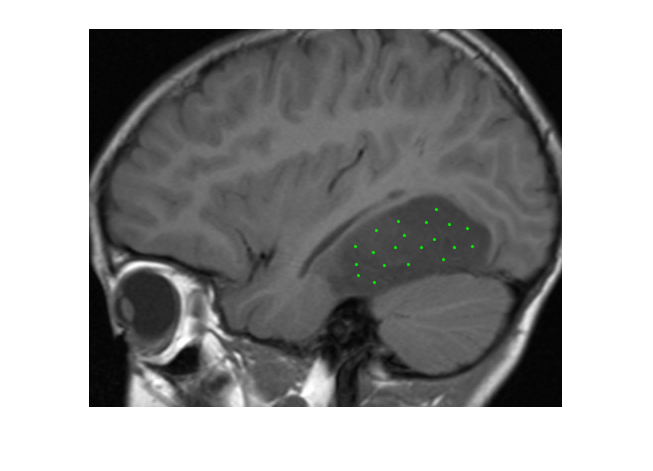

%Load dataset
Im = load("tumorData.mat");
Im = Im.data;
%Load selected tumor points
SelPoints = cell2mat(struct2cell(load("SelPoints.mat"))');
xSelPoints = round(SelPoints(:, 1));
ySelPoints = round(SelPoints(:, 2));
%Visualize the selected points 
figure();
imshow(Im, [])
hold on;
plot(xSelPoints, ySelPoints, '.g')
hold off;

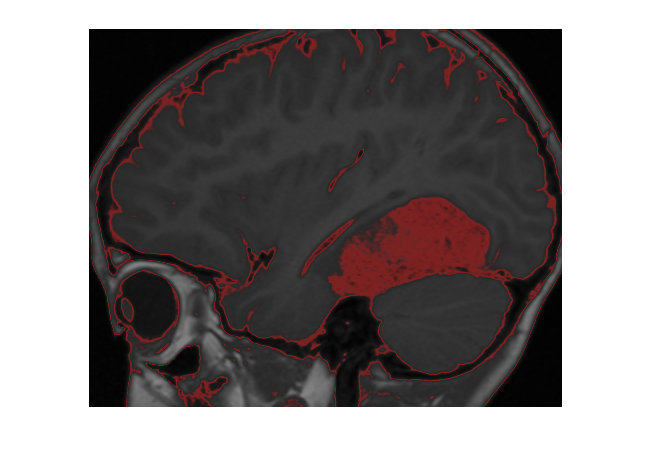

%Calculate the mean and standard deviation of the intensities of selected points
ImSelIntensity = diag(Im(ySelPoints, xSelPoints));
tumorMean = mean(ImSelIntensity);
tumorVar = var(ImSelIntensity);
%Calculate the mean and standard deviation of all image intensities
ImMean = mean(Im(:));
ImVar = var(Im(:));

%Define the prior probabilities
pi = [0.2 0.8];

%Calculate posterior probabilities
posteriorLab1 = normpdf(Im, tumorMean, sqrt(tumorVar)) * pi(1) ./ ...
    (normpdf(Im, tumorMean, sqrt(tumorVar)) * pi(1) + ...
    normpdf(Im, ImMean, sqrt(ImVar)) * pi(2));

%Since there are only 2 classes, the posterior probability of the 2nd class
%can be calculates as 1 - P
posteriorLab2 = 1 - posteriorLab1;
rgb = zeros([size(Im) 3]);
rgb(:, :, 1) = posteriorLab1;
ImFused = imfuse(Im, rgb, 'blend');
imshow(ImFused)

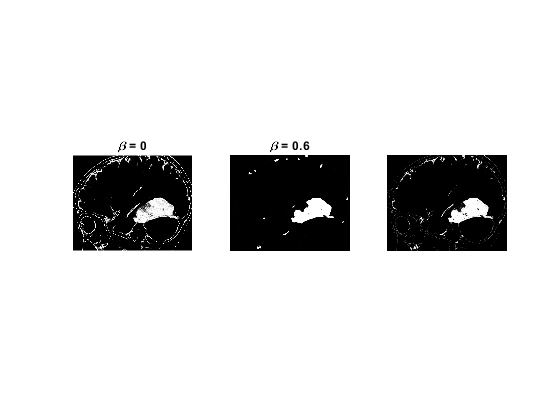

%Define the penalization parameter Beta and obtain 
%indices of each of the non-neighbouring pixels to update
tmp1 = ones(size(Im, 1), 1);
tmp1( 1 : 2 : end ) = 0;
tmp2 = ones( 1, size(Im, 2 ) );
tmp2( 1 : 2 : end ) = 0;
whiteIndices = find( kron( tmp1, tmp2 ) );
blackIndices = find( kron( ~tmp1, ~tmp2 ) );
redIndices = find( kron( ~tmp1, tmp2 ) );
greenIndices = find( kron( tmp1, ~tmp2 ) );

indicesToUpdateCell{1} = whiteIndices;
indicesToUpdateCell{2} = blackIndices;
indicesToUpdateCell{3} = redIndices;
indicesToUpdateCell{4} = greenIndices;

%Set the initial approximation of distributions
qOfClass1 = posteriorLab1;
qOfClass2 = posteriorLab2;

%Perform classification for Beta = 0.3
Beta = 0.3;
for k = 1:100
    for colorIndex = 1:4
        %Create matrices which calculate the number of neighbours
        %that are different from each of the classes
        numOfDiffNeigh1 = numberOfDifferentNeighbours(qOfClass1);
        numOfDiffNeigh2 = numberOfDifferentNeighbours(qOfClass2);
        %Extract indices which we want to simultaneously update
        indicesToUpdate = indicesToUpdateCell{colorIndex};
        %Extract the neighbours and the image with the corresponding
        %indices
        tmpNeighbour1 = numOfDiffNeigh1(indicesToUpdate);
        tmpNeighbour2 = numOfDiffNeigh2(indicesToUpdate);
        ImTmp = Im(indicesToUpdate);
        %Update the Markov random field posterior
        [qOfClass1(indicesToUpdate), qOfClass2(indicesToUpdate)] = ...
            MRFPostIter(ImTmp, ImMean, ImVar, tumorMean, tumorVar, pi, ...
            tmpNeighbour1, tmpNeighbour2, Beta);
        
    end
end
imshow(qOfClass1, []);

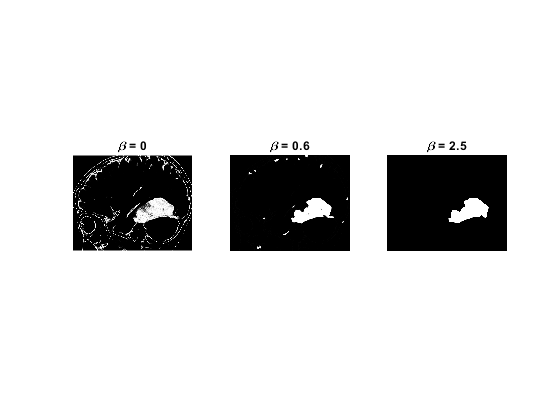


figure();

%Perform classification for Beta = 0
Beta = 0;
for k = 1:100
    for colorIndex = 1:4
        %Create matrices which calculate the number of neighbours
        %that are different from each of the classes
        numOfDiffNeigh1 = numberOfDifferentNeighbours(qOfClass1);
        numOfDiffNeigh2 = numberOfDifferentNeighbours(qOfClass2);
        %Extract indices which we want to simultaneously update
        indicesToUpdate = indicesToUpdateCell{colorIndex};
        %Extract the neighbours and the image with the corresponding
        %indices
        tmpNeighbour1 = numOfDiffNeigh1(indicesToUpdate);
        tmpNeighbour2 = numOfDiffNeigh2(indicesToUpdate);
        ImTmp = Im(indicesToUpdate);
        %Update the Markov random field posterior
        [qOfClass1(indicesToUpdate), qOfClass2(indicesToUpdate)] = ...
            MRFPostIter(ImTmp, ImMean, ImVar, tumorMean, tumorVar, pi, ...
            tmpNeighbour1, tmpNeighbour2, Beta);
        
    end
end
subplot(1, 3, 1);
imshow(qOfClass1, []), title("\beta = 0");

%Perform classification for Beta = 0.6
Beta = 0.6;
for k = 1:100
    for colorIndex = 1:4
        %Create matrices which calculate the number of neighbours
        %that are different from each of the classes
        numOfDiffNeigh1 = numberOfDifferentNeighbours(qOfClass1);
        numOfDiffNeigh2 = numberOfDifferentNeighbours(qOfClass2);
        %Extract indices which we want to simultaneously update
        indicesToUpdate = indicesToUpdateCell{colorIndex};
        %Extract the neighbours and the image with the corresponding
        %indices
        tmpNeighbour1 = numOfDiffNeigh1(indicesToUpdate);
        tmpNeighbour2 = numOfDiffNeigh2(indicesToUpdate);
        ImTmp = Im(indicesToUpdate);
        %Update the Markov random field posterior
        [qOfClass1(indicesToUpdate), qOfClass2(indicesToUpdate)] = ...
            MRFPostIter(ImTmp, ImMean, ImVar, tumorMean, tumorVar, pi, ...
            tmpNeighbour1, tmpNeighbour2, Beta);
        
    end
end
subplot(1, 3, 2);
imshow(qOfClass1, []), title("\beta = 0.6");

%Perform classification for Beta = 2.5
Beta = 2.5;
for k = 1:100
    for colorIndex = 1:4
        %Create matrices which calculate the number of neighbours
        %that are different from each of the classes
        numOfDiffNeigh1 = numberOfDifferentNeighbours(qOfClass1);
        numOfDiffNeigh2 = numberOfDifferentNeighbours(qOfClass2);
        %Extract indices which we want to simultaneously update
        indicesToUpdate = indicesToUpdateCell{colorIndex};
        %Extract the neighbours and the image with the corresponding
        %indices
        tmpNeighbour1 = numOfDiffNeigh1(indicesToUpdate);
        tmpNeighbour2 = numOfDiffNeigh2(indicesToUpdate);
        ImTmp = Im(indicesToUpdate);
        %Update the Markov random field posterior
        [qOfClass1(indicesToUpdate), qOfClass2(indicesToUpdate)] = ...
            MRFPostIter(ImTmp, ImMean, ImVar, tumorMean, tumorVar, pi, ...
            tmpNeighbour1, tmpNeighbour2, Beta);
        
    end
end
subplot(1, 3, 3);
imshow(qOfClass1, []), title("\beta = 2.5");

%Calculate the area of the tumor for Beta 2.5
sum(qOfClass1 > qOfClass2, "all")

ans = 8988

%verfiy the area can be approximated by the sum of Markov 
%posteriors ((4.24 in lecture notes))
sum(qOfClass1, "all")

ans = 8.9778e+03